# Bayesian tomography

**Author**: Abakumov Ivan

**Publication date**: 15th Feb 2018

## Introduction

for the purpose of education

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Define grid and velocity model

% Make G-file
G=GridClass;

%    [m]        [m]       [m]          [s]
G.x0=-150;     G.y0=0;    G.z0=250;    G.t0 = 0.00;            % initial point
G.nx=201;      G.ny=1;    G.nz=201;    G.nt = 300;             % grid size
G.dx=1.5;      G.dy=0;    G.dz=1.5;    G.dt = 0.001;           % grid step (meter)

G.gridInfo;

Information about grid:
x0=-150, dx=1.5, Nx=201.
y0=0, dy=0, Ny=1.
z0=250, dz=1.5, Nz=201.
t0=0, dt=0.001, Nt=300.


G.setGrid;
Gold=G.oldGrid;


[XX, ZZ] = meshgrid(G.xx, G.zz);

## Acquisition

acq.sx = [-150 -150 -150 -150 -150 -150 -150 -100 -50 0    50 100 150 150 150 150 150 150 150 100 50    0 -50 -100];
acq.sz = [ 250  300  350  400  450  500  550  550 550 550 550 550 550 500 450 400 350 300 250 250 250 250 250  250];

acq.rx = [-150 -150 -150 -150 -150 -150 -150 -100 -50 0    50 100 150 150 150 150 150 150 150 100 50    0 -50 -100];
acq.rz = [ 250  300  350  400  450  500  550  550 550 550 550 550 550 500 450 400 350 300 250 250 250 250 250  250];

acq.gsx = x2grid(acq.sx, G.x0, G.dx, G.nx); 
acq.gsz = x2grid(acq.sz, G.z0, G.dz, G.nz); 
acq.grx = x2grid(acq.rx, G.x0, G.dx, G.nx); 
acq.grz = x2grid(acq.rz, G.z0, G.dz, G.nz);

## True velocity model

tvelmod = zeros(G.nx, G.nz); 
for i=1:G.nx
    tvelmod(i,:) = 2000 + 1.25*G.dx*i; 
end

tvelmod(33:100, 33:74) = 3000; 
tvelmod(100:167, 127:167) = 1500; 



figure(1)

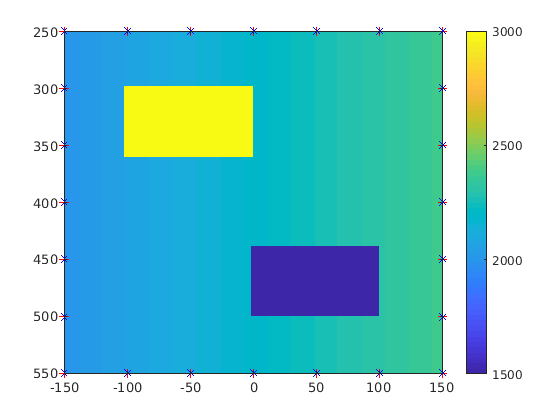

imagesc(G.xx, G.zz, tvelmod'); 
hold on
 colorbar;
plot(acq.sx, acq.sz, 'r*')
plot(acq.rx, acq.rz, 'bx')

## Calculate exact traveltimes

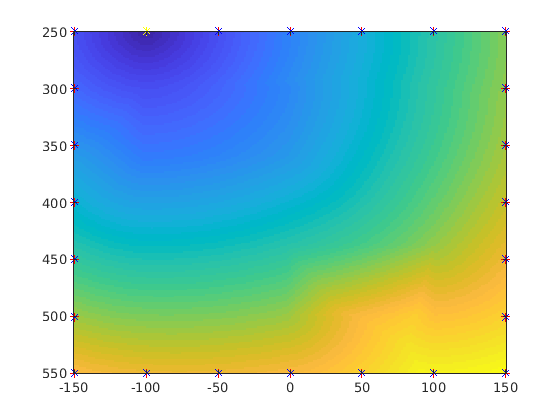

nshot = length(acq.sx); 
nrece = length(acq.rx); 

texact = zeros(nshot, nrece); 

for s=1:nshot
    S = [ acq.sx(s) acq.sz(s)];
    tti  = FSM2D(Gold,S,tvelmod); 
    for r=1:nrece
        texact(s,r) = tti(acq.grx(r), acq.grz(r));  
    end
end

sigma = 0.001; 
noise = sigma*randn(size(texact));
texact = texact + noise;


figure(2)
imagesc(G.xx, G.zz, tti');
hold on
plot(acq.sx, acq.sz, 'r*')
plot(acq.rx, acq.rz, 'bx')
plot(acq.sx(s), acq.sz(s), 'y*')

## Parameters

number_of_cells = 40; 
number_of_parameters=3*number_of_cells;
number_of_particles=1000;   
number_of_iterations=10000;   

XMIN = G.x0; XMAX = G.mx;
ZMIN = G.z0; ZMAX = G.mz; 
VMIN = 1000; VMAX = 4000; 

Xmin = [XMIN*ones(number_of_cells,1);ZMIN*ones(number_of_cells,1);VMIN*ones(number_of_cells,1)];
Xmax = [XMAX*ones(number_of_cells,1);ZMAX*ones(number_of_cells,1);VMAX*ones(number_of_cells,1)]; 
Vmax = [(XMAX-XMIN)/100*ones(number_of_cells,1);...
        (ZMAX-ZMIN)/100*ones(number_of_cells,1);...
        (VMAX-VMIN)/100*ones(number_of_cells,1)];  

Vmin = - Vmax; 
    
saveF = zeros(number_of_iterations,number_of_particles);
saveX = zeros(number_of_parameters,number_of_particles);


number_of_iterations = 4000;
tic
[saveF, saveX] = make_markov_chain(G,acq,XX,ZZ,texact,sigma,Xmin,Xmax,Vmin,Vmax,number_of_parameters,number_of_iterations)

saveF = 	1.0e+-3 *

    0.0010
    0.0010
    0.0010
    0.0011
    0.0011
    0.0010
    0.0008
    0.0005
    0.0005
    0.0005


saveX = 	1.0e+03 *

    0.0405   -0.1283    0.1310    0.0614   -0.1488   -0.0924    0.0742   -0.0263    0.1322    0.0955   -0.0084   -0.0385   -0.0092    0.1203    0.1463    0.1244    0.1286    0.1112    0.0004    0.0943    0.0344   -0.1425    0.1129    0.1347   -0.0685   -0.1130   -0.1390   -0.0992   -0.0753   -0.1272    0.1096    0.1341    0.0963   -0.0398    0.0930   -0.1359    0.0609    0.0724   -0.0220    0.0686    0.3679    0.3714    0.2674    0.3471    0.3158    0.4036    0.3875    0.4891    0.3788    0.4210
    0.0418   -0.1305    0.1323    0.0591   -0.1461   -0.0939    0.0756   -0.0285    0.1336    0.0970   -0.0064   -0.0376   -0.0121    0.1230    0.1487    0.1225    0.1256    0.1126    0.0032    0.0967    0.0362   -0.1429    0.1123    0.1354   -0.0665   -0.1103   -0.1370   -0.0997   -0.0753   -0.1244    0.1068    0.1357    0.0971   -0.0413    0.0932   -0.1343    0.0611    0.0710   -0.0200    0.0689    0.3694    0.3713    0.2665    0.3442    0.3182    0.4035    0.3887    0.491

toc

Elapsed time is 67.068605 seconds.


## Visualize results

meanV = zeros(size(tvelmod)); 
stdV = zeros(size(tvelmod)); 
F = saveF(end,:);
W = exp(-F.^2/2);       % likelyhood

for i=1:1000
    Xn = saveX(:,i);
    velmod = voronoi2velmod(Xn,G,XX,ZZ);
    meanV = meanV + W(i)*velmod; 
end
meanV = meanV/sum(W);

for i=1:1000
    Xn = saveX(:,i);
    velmod = voronoi2velmod(Xn,G,XX,ZZ);
    stdV = W(i)*(velmod-meanV).^2; 
end

stdV = stdV/sum(W); 
stdV = sqrt(stdV);

figure(1)
subplot(2,2,1)
imagesc(tvelmod')
subplot(2,2,2)
imagesc(meanV')
subplot(2,2,3)
imagesc(meanV'-tvelmod');
subplot(2,2,4)
imagesc(stdV')